**LEP 6-4 : Algorithm for Gas Phase Reaction**

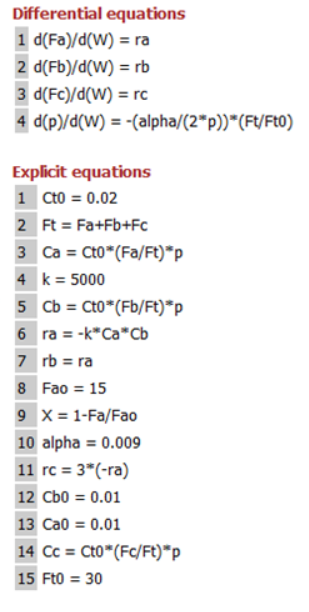

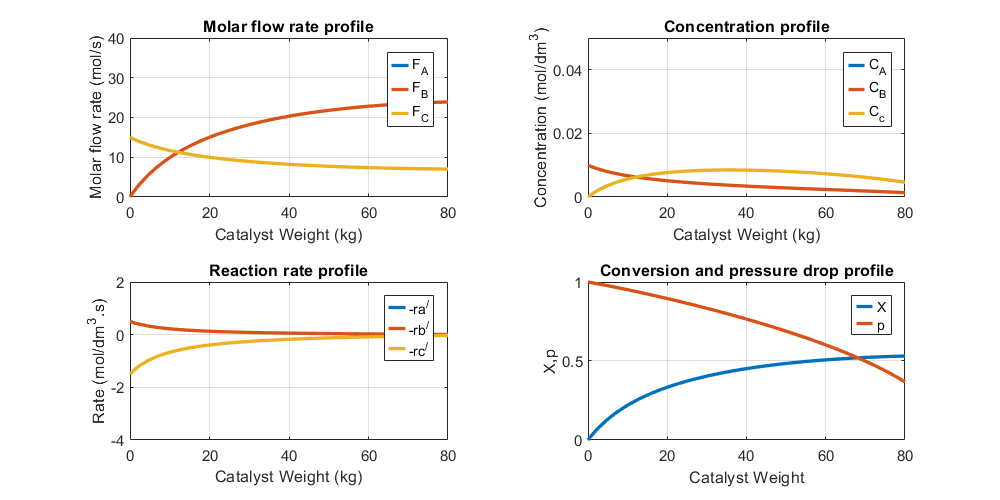

Wspan = [0 80]; % Range for the Weight of the Catalyst. 
y0 = [15 15 0 1]; % Initial values for the dependent variables Fa, Fb, Fc and p
alpha = 0.009; 
k = 5000;  
Ca0 = 0.01; 
Cb0 = 0.01;
[w,y]=ode45(@(w,y)ODEfun(w,y,alpha,k,Ca0,Cb0),Wspan,y0);
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,800,400])
nexttile
plot(w,y(:,1),w,y(:,3),w,y(:,2),'LineWidth',2)
xlabel('Catalyst Weight (kg)')
ylabel('Molar flow rate (mol/s)')
leg=legend('F_A','F_B','F_C');
title('Molar flow rate profile')
leg.ItemTokenSize=[10,10];
axis([0 80 0 40])
grid on
z=size(y);
Fao=15;
Ct0 =Ca0 +Cb0 ; 
for i=1:z(1,1)
X(i)=1-y(i,1)/Fao;
Ft(i)=y(i,1)+y(i,2)+y(i,3);
Ca(i) = Ct0*(y(i,1)/Ft(i))*y(i,4);
Cb(i) = Ct0*(y(i,2)/Ft(i))*y(i,4); 
Cc(i) = Ct0*(y(i,3)/Ft(i))*y(i,4);
ra(i) = -k*Ca(i)*Cb(i); 
rb(i) = ra(i); 
rc(i) = 3*(-ra(i));
end
nexttile
plot(w,Ca(1:z(1,1)),w,Cb(1:z(1,1)),w,Cc(1:z(1,1)),'LineWidth',2)
xlabel('Catalyst Weight (kg)')
ylabel('Concentration (mol/dm^3)')
leg=legend('C_A','C_B','C_c');
title('Concentration profile')
leg.ItemTokenSize=[10,10];
axis([0 80 0 0.05])
grid on
nexttile
plot(w,-ra(1:z(1,1)),w,-rb(1:z(1,1)),w,-rc(1:z(1,1)),'LineWidth',2)
xlabel('Catalyst Weight (kg)')
ylabel('Rate (mol/dm^3.s)')
leg=legend('-ra^/','-rb^/','-rc^/');
title('Reaction rate profile')
leg.ItemTokenSize=[10,10];
axis([0 80 -4 2])
grid on
nexttile
plot(w,X(1:z(1,1)),w,y(:,4),'LineWidth',2)
xlabel('Catalyst Weight')
ylabel('X,p')
leg=legend('X','p');
title('Conversion and pressure drop profile')
leg.ItemTokenSize=[10,10];
axis([0 80 0 1])
grid on

function dYfuncvecdW = ODEfun(V,Yfuncvec,alpha,k,Ca0,Cb0); 
Fa = Yfuncvec(1); 
Fb= Yfuncvec(2); 
Fc= Yfuncvec(3);
p= Yfuncvec(4);
% Explicit equations

Ct0 =Ca0 +Cb0 ; 
Ft0 = 30;
Fao=15;
X=1-Fa/Fao;
Ft=Fa+Fb+Fc;
Ca = Ct0*(Fa/Ft)*p;
Cb = Ct0*(Fb/Ft)*p; 
Cc = Ct0*(Fc/Ft)*p; 
ra = -k*Ca*Cb; 
rb = ra; 
rc = 3*(-ra); 
% Differential equations
dFadW = ra; 
dFbdW = rb; 
dFcdW = rc; 
dpdW = -(alpha/(2*p))*(Ft/Ft0); 
dYfuncvecdW =[dFadW; dFbdW;dFcdW;dpdW]; 
end